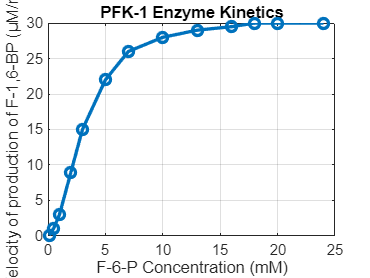

% Experimental data
F6P_concentration = [0.1, 0.5, 1, 2, 3, 5, 7, 10, 13, 16, 18, 20, 24];
velocity = [0.1, 1.1, 3, 9, 15, 22, 26, 28, 29, 29.5, 30, 30, 30];

% Plotting the data
figure;
plot(F6P_concentration, velocity, 'o-', 'LineWidth', 2);
xlabel('F-6-P Concentration (mM)');
ylabel('Velocity of production of F-1,6-BP (µM/min)');
title('PFK-1 Enzyme Kinetics');
grid on;

% Michaelis-Menten model
mm_model = @(params, S) params(1) * S ./ (params(2) + S);

% Initial guess for parameters [Vmax, Km]
initial_guess = [30, 3];

% Nonlinear regression
params = lsqcurvefit(mm_model, initial_guess, F6P_concentration, velocity);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



% Extract parameters
Vmax = params(1);
Km = params(2);

fprintf('Michaelis-Menten parameters:\n Vmax = %.2f µM/min\n Km = %.2f mM\n', Vmax, Km);

Michaelis-Menten parameters:
 Vmax = 38.44 µM/min
 Km = 4.72 mM


% Hill model
hill_model = @(params, S) params(1) * S.^params(2) ./ (params(3).^params(2) + S.^params(2));

% Initial guess for parameters [Vmax, n, Kd]
initial_guess = [30, 2, 3];

% Nonlinear regression
params = lsqcurvefit(hill_model, initial_guess, F6P_concentration, velocity);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



% Extract parameters
Vmax = params(1);
Hill_n = params(2);
Kd = params(3);

fprintf('Hill dynamics parameters:\n Vmax = %.2f µM/min\n Hill coefficient = %.2f\n Hill constant (Kd) = %.2f mM\n', Vmax, Hill_n, Kd);

Hill dynamics parameters:
 Vmax = 30.70 µM/min
 Hill coefficient = 1.99
 Hill constant (Kd) = 3.08 mM
